clear;clc;close all;

numMatches=[2;2;4;4;3;1];

x=optimvar('x',6,6,'type','integer','LowerBound',0,'UpperBound',1);
prob=optimproblem;
prob.Objective=sum(x,"all");
prob.Constraints.row= sum(x,1)==numMatches';
prob.Constraints.col= sum(x,2)==numMatches;
prob.Constraints.symmetry=[];
for n1=1:6
    for n2=n1+1:6
        prob.Constraints.symmetry ...
            =[prob.Constraints.symmetry;
            x(n1,n2)==x(n2,n1)];
    end
end
prob.Constraints.zeros=[];
for n1=1:6
    prob.Constraints.zeros(n1)= x(n1,n1)==0;
end

prob.Constraints.pastSol=[];

figure;
tiledlayout(1,5)
for k=1:10
    k
    sol=solve(prob);
    sol.x
    if isempty(sol.x)
        break;
    else
    g=graph(sol.x,{'A','B','C','D','E','F'});
    nexttile;
    plt=plot(g,'Layout','circle');
    set(gca,'xcolor','none');
    set(gca,'ycolor','none');
    plt.NodeFontSize=12;
    prob.Constraints.pastSol ...
        =[prob.Constraints.pastSol;
        sum(x.*(sol.x),'all')<=sum(numMatches)-1e-4];
    end
end

k = 1

intlinprog を使用して問題を解決しています。
LP:                Optimal objective value is 16.000000.                                            


最適解が見つかりました。

intlinprog がルート ノードで停止しました。最適値のギャップの許容誤差内に目的値が存在するためであり、ギャップの許容誤差は options.AbsoluteGapTolerance = 0 です。intcon の変数は、許容誤差内の整数であり、許容誤差は options.IntegerTolerance = 1e-05 です。



ans =      0     0     1     1     0     0
     0     0     1     0     1     0
     1     1     0     1     1     0
     1     0     1     0     1     1
     0     1     1     1     0     0
     0     0     0     1     0     0


k = 2

intlinprog を使用して問題を解決しています。
LP:                Optimal objective value is 16.000000.                                            


最適解が見つかりました。

intlinprog がルート ノードで停止しました。最適値のギャップの許容誤差内に目的値が存在するためであり、ギャップの許容誤差は options.AbsoluteGapTolerance = 0 です。intcon の変数は、許容誤差内の整数であり、許容誤差は options.IntegerTolerance = 1e-05 です。



ans =      0     0     0     1     1     0
     0     0     1     1     0     0
     0     1     0     1     1     1
     1     1     1     0     1     0
     1     0     1     1     0     0
     0     0     1     0     0     0


k = 3

intlinprog を使用して問題を解決しています。
LP:                Optimal objective value is 16.000000.                                            


最適解が見つかりました。

intlinprog がルート ノードで停止しました。最適値のギャップの許容誤差内に目的値が存在するためであり、ギャップの許容誤差は options.AbsoluteGapTolerance = 0 です。intcon の変数は、許容誤差内の整数であり、許容誤差は options.IntegerTolerance = 1e-05 です。



ans =      0     0     1     1     0     0
     0     0     1     1     0     0
     1     1     0     1     1     0
     1     1     1     0     1     0
     0     0     1     1     0     1
     0     0     0     0     1     0


k = 4

intlinprog を使用して問題を解決しています。
LP:                Optimal objective value is 16.000000.                                            

Cut Generation:    Applied 1 cover cut.                                                             
                   Lower bound is 16.000000.                                                        
                   Relative gap is 0.00%.                                                          


最適解が見つかりました。

intlinprog がルート ノードで停止しました。最適値のギャップの許容誤差内に目的値が存在するためであり、ギャップの許容誤差は options.AbsoluteGapTolerance = 0 です。intcon の変数は、許容誤差内の整数であり、許容誤差は options.IntegerTolerance = 1e-05 です。



ans =      0     0     1     0     1     0
     0     0     1     1     0     0
     1     1     0     1     1     0
     0     1     1     0     1     1
     1     0     1     1     0     0
     0     0     0     1     0     0


k = 5

intlinprog を使用して問題を解決しています。
LP:                Optimal objective value is 16.000000.                                            

Cut Generation:    Applied 1 cover cut.                                                             
                   Lower bound is 16.000000.                                                        
                   Relative gap is 0.00%.                                                          


最適解が見つかりました。

intlinprog がルート ノードで停止しました。最適値のギャップの許容誤差内に目的値が存在するためであり、ギャップの許容誤差は options.AbsoluteGapTolerance = 0 です。intcon の変数は、許容誤差内の整数であり、許容誤差は options.IntegerTolerance = 1e-05 です。



ans =      0     0     1     1     0     0
     0     0     0     1     1     0
     1     0     0     1     1     1
     1     1     1     0     1     0
     0     1     1     1     0     0
     0     0     1     0     0     0


k = 6

intlinprog を使用して問題を解決しています。
LP:                Optimal objective value is 16.000000.                                            

Cut Generation:    Applied 1 cover cut.                                                             
                   Lower bound is 16.000000.                                                        


実行可能解は見つかりませんでした。

intlinprog が停止しました。この理由は、制約を満たす整数点がないためです。




ans =

     []



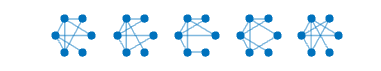

% set(gcf,'paperposition',[3.0917 9.2937 2*14.8167 11.1125/2])
set(gcf, 'position', [320 1298 2*560 420/2])
exportgraphics(gcf,'fig_Exercise_ChapA_graph.pdf');